# Edge Detection

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-12-12

#### Introduction

clear; clc; close all;

img = imread('brick-wall-bricks-stone-207142.jpg');
img = imresize(img,0.3);
imgg = rgb2gray(img);
img_edge = edge(imgaussfilt(imgg, 3),'Canny');

figure(1); imshow(img_edge);

#### Origin of Edges

clear; close all; clc;

img_org = imread('architecture-blank-space-blue-sky-921294.jpg');
img = imresize(img_org,0.2);

% surface normal discontinuity
pos1 = [2804.5 736.51 311.98 221.98];

figure(1); 
subplot(121); imshow(img); hold on; 
rectangle('Position', pos1*0.2,'EdgeColor','r'); hold off;
subplot(122); imshow(imcrop(img_org, pos1)); 

% material & color discontinuity
pos2 = [2528.5 976.51 266.98 206.98];

figure(2); 
subplot(121); imshow(img); hold on; 
rectangle('Position', pos2*0.2,'EdgeColor','r'); hold off;
subplot(122); imshow(imcrop(img_org, pos2)); 

% lighting discontinuity
pos3 = [ 1126.5 2062.5 347.98 272.98];

figure(3); 
subplot(121); imshow(img); hold on; 
rectangle('Position', pos3*0.2,'EdgeColor','r'); hold off;
subplot(122); imshow(imcrop(img_org, pos3)); 

#### Characterizing Edge

close all; clc; clear;

img = repmat(repelem([1 0 1],100), 300, 1);
img = imgaussfilt(img, 10);
fig1 = figure(1); 
subplot(131); imagesc(img); colormap('gray'); set(gca, 'xtick',[], 'ytick', []);
hold on; line([0 300],[150 150], 'color', 'r'); hold off;
sig = img(150,:);
subplot(132); plot(sig); set(gca, 'xtick',[], 'ytick', []);
subplot(133); plot(diff(sig)); set(gca, 'xtick',[], 'ytick', []);
set(fig1,'Position', [100 100 800 200]);

#### Intensity change and edges

close all; clc; clear;

img = repmat(repelem([1 0.5 1],100), 300, 1);
img = imgaussfilt(img, 5);
fig1 = figure(1); 
subplot(131); imshow(img); 
subplot(132); imshow(img*0.5); 
subplot(133); imshow(img*0.1); 
set(fig1,'Position', [100 100 800 200]);

#### Image Gradient

clear; close all; clc

img = imread('brick-wall-bricks-stone-207142.jpg');
img = imresize(img,0.4);
imgg = rgb2gray(img);
imgg = im2double(imgg);

prewitt_x = [-ones(3,1) zeros(3,1) ones(3,1)];
prewitt_y = - transpose(prewitt_x);

fx= imfilter(imgg,prewitt_x);
fy= imfilter(imgg,prewitt_y);
fxy = sqrt(fx.^2 + fy.^2);

fig1 = figure(1);
subplot(221); imshow(imgg);
subplot(222); imshow(fx);
subplot(223); imshow(fy);
subplot(224); imshow(fxy);
set(fig1,'Position', [100 100 700 400]);

#### Effects of Noise (2D)

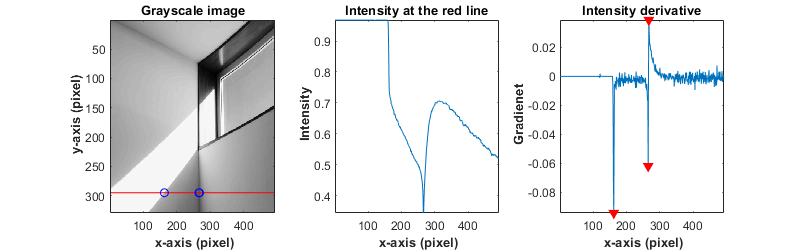

img_org = imread('architecture-blank-space-blue-sky-921294.jpg');
img_org = im2double(img_org);
imgg = rgb2gray(img_org);
img = imresize(imgg,0.1);

fig1 = figure(1);
ax1 = subplot(131); imagesc(img); colormap(gray); hold on;
line([0 size(img,2)], [295 295], 'color', 'r'); hold off;
title('Grayscale image')
xlabel('\bf x-axis (pixel)')
ylabel('\bf y-axis (pixel)')

sig = img(295,:);
ax2 = subplot(132); plot(1:numel(sig), sig);axis tight; 
title('Intensity at the red line')
xlabel('\bf x-axis (pixel)')
ylabel('\bf Intensity')

diff_sig = diff(sig);
ax3 = subplot(133); plot(1:numel(diff_sig), diff_sig); axis tight;
title('Intensity derivative')
xlabel('\bf x-axis (pixel)')
ylabel('\bf Gradienet')
set(fig1,'Position', [100 100 800 250]);

[pks_1,locs_1] = findpeaks(diff_sig,'MinPeakHeight',0.03,'MinPeakDistance',10);
[pks_2,locs_2] = findpeaks(-diff_sig,'MinPeakHeight',0.03,'MinPeakDistance',10);
hold(ax1, 'on'); plot(ax1, [locs_1 locs_2]+1, [295 295 295], 'ob'); hold(ax1, 'off');
hold(ax3, 'on'); plot(ax3, [locs_1 locs_2], [pks_1 -pks_2], 'rv', 'MarkerFaceColor', 'r'); 
hold(ax3, 'off');

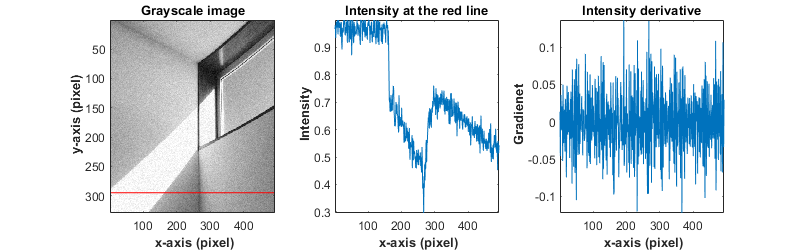


fig2 = figure(2);
img = imnoise(img,'gaussian', 0, 0.001);
ax1 = subplot(131); imagesc(img); colormap(gray); hold on;
line([0 size(img,2)], [295 295], 'color', 'r'); hold off;
title('Grayscale image')
xlabel('\bf x-axis (pixel)')
ylabel('\bf y-axis (pixel)')

sig = img(295,:);
ax2 = subplot(132); plot(1:numel(sig), sig);axis tight; 
title('Intensity at the red line')
xlabel('\bf x-axis (pixel)')
ylabel('\bf Intensity')

diff_sig = diff(sig);
ax3 = subplot(133); plot(1:numel(diff_sig), diff_sig); axis tight;
title('Intensity derivative')
xlabel('\bf x-axis (pixel)')
ylabel('\bf Gradienet')
set(fig2,'Position', [100 100 800 250]);

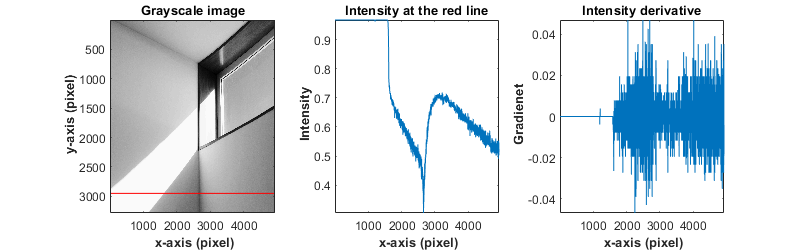


fig3 = figure(3); % original resolution image
ax1 = subplot(131); imagesc(imgg); colormap(gray); hold on;
line([0 size(imgg,2)], [2950 2950], 'color', 'r'); hold off;
title('Grayscale image')
xlabel('\bf x-axis (pixel)')
ylabel('\bf y-axis (pixel)')

sig = imgg(2950,:);
ax2 = subplot(132); plot(1:numel(sig), sig);axis tight; 
title('Intensity at the red line')
xlabel('\bf x-axis (pixel)')
ylabel('\bf Intensity')

diff_sig = diff(sig);
ax3 = subplot(133); plot(1:numel(diff_sig), diff_sig); axis tight;
title('Intensity derivative')
xlabel('\bf x-axis (pixel)')
ylabel('\bf Gradienet')
set(fig3,'Position', [100 100 800 250]);

#### Effects of noise (1D)

close all; clc; clear;

img = repmat(repelem([0.2 0.8],200), 400, 1);
img = imgaussfilt(img, 5);

fig1 = figure(1); 
img = imnoise(img,'gaussian', 0, 0.001);
imagesc(img); colormap('gray'); set(gca, 'xtick',[], 'ytick', []);
hold on; line([0 400],[200 200], 'color', 'r'); hold off;
sig = img(150,:);
set(fig1,'Position', [100 100 300 300]);

fig2 = figure(2);
subplot(211);plot(1:numel(sig), sig); axis tight;
xlabel('\bf x-axis (pixel)')
ylabel('\bf f(x)'); ylim([-0.1 1.1])

subplot(212);diff_sig = diff(sig);
plot(1:numel(diff_sig), diff_sig); axis tight;
xlabel('\bf x-axis (pixel)')
ylabel('\bf df(x)/dx'); 
set(fig2,'Position', [100 100 700 500]);

fig3 = figure(3);
subplot(411); plot(1:numel(sig), sig, 'linewidth', 1.5); axis tight;
ylabel('\bf f(x)','Interpreter', 'latex'); xlim([0 numel(sig)]);
hYLabel = get(gca,'YLabel');grid on;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

windSize = 50;
h = gausswin(windSize,3);
subplot(412); plot(1:numel(h), h, 'linewidth', 1.5); axis tight;
ylabel('\bf h(x)','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

fh = conv(sig,h,'valid');
subplot(413); plot(windSize/2:numel(fh)+windSize/2-1, fh, 'linewidth', 1.5); axis tight;
ylabel('\bf f * h','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

diff_fh = diff(fh);
subplot(414); plot(windSize/2:numel(diff_fh)+windSize/2-1, diff_fh, 'linewidth', 1.5); axis tight;
ylabel('$\frac{d(f * h)}{dx}$','Interpreter', 'latex'); 
xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel'); grid on;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

set(fig3,'Position', [100 100 900 500]);

fig4 = figure(4);
subplot(311); plot(1:numel(sig), sig, 'linewidth', 1.5); axis tight;
ylabel('\bf f(x)','Interpreter', 'latex'); xlim([0 numel(sig)]);
hYLabel = get(gca,'YLabel');grid on;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

windSize = 51;
h = gausswin(windSize,3);
diff_h = diff(h);
subplot(312); plot(1:numel(diff_h), diff_h, 'linewidth', 1.5); axis tight;
ylabel('\bf h''(x)','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

fh = conv(sig,diff_h,'valid');
subplot(313); plot(windSize/2:numel(fh)+windSize/2-1, fh, 'linewidth', 1.5); axis tight;
ylabel('\bf f * h''','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

set(fig4,'Position', [100 100 900 400]);


#### Derivative of a Guassian Filter

numSize = 3;
[x, y] = meshgrid(1:numSize); 
x = x-(round(numSize/2));
y = y-(round(numSize/2));

sigma = 1;

G_sigma = 1/(2*pi*sigma^2)*exp(-(x.^2 + y.^2)/(2*sigma^2));
G_sigma = G_sigma/sum(G_sigma,'all');

fig2 = figure(2);
subplot(121); h = fspecial('gaussian', 31,4);
surf(h); axis tight; colormap(jet)
xlabel('X-axis'); ylabel('Y-axis');
zlabel('Amplitude')
subplot(122); surf(h); view(0,90);
xlabel('X-axis'); ylabel('Y-axis'); axis tight
set(fig2,'Position', [100 100 800 300]);

fig3 = figure(3);
subplot(121); 
diff_h_x = diff(h,1,2);
surf(diff_h_x); axis tight; colormap(jet)
xlabel('X-axis'); ylabel('Y-axis');
zlabel('Amplitude')
subplot(122); surf(diff_h_x); view(0,90);
xlabel('X-axis'); ylabel('Y-axis'); axis tight
set(fig3,'Position', [100 100 800 300]);

fig4 = figure(4);
subplot(121); 
diff_h_y = diff(h,1,1);
surf(diff_h_y); axis tight; colormap(jet)
xlabel('X-axis'); ylabel('Y-axis');
zlabel('Amplitude')
subplot(122); surf(diff_h_y); view(0,90);
xlabel('X-axis'); ylabel('Y-axis'); axis tight
set(fig4,'Position', [100 100 800 300]);

#### Sobel Operator

clear; close all; clc

img = repmat(repelem([0.8 0.2],200), 400, 1);
fig1 = figure(1); 
subplot(121);
imagesc(img); colormap('gray'); set(gca, 'xtick',[], 'ytick', []);
h = fspecial('gaussian', 31,5.5);
diff_h_x = diff(h,1,2);
subplot(122);
surf(diff_h_x); axis tight; colormap(gray)
xlabel('X-axis'); ylabel('Y-axis');
zlabel('Amplitude');view(0,90);
set(fig1,'Position', [100 100 600 300]);

img = imread('brick-wall-bricks-stone-207142.jpg');
img = imresize(img,0.4);
imgg = rgb2gray(img);
imgg = im2double(imgg);

prewitt_x = [-ones(3,1) zeros(3,1) ones(3,1)];
prewitt_y = - transpose(prewitt_x);

sobel_x = prewitt_x;
sobel_x(2,1)=-2; sobel_x(2,3)=2;
sobel_y = -transpose(sobel_x);

fx= imfilter(imgg,sobel_x);
fy= imfilter(imgg,sobel_y);
fxy = sqrt(fx.^2 + fy.^2);

fig2 = figure(2);
subplot(221); imshow(imgg);
subplot(222); imshow(fx);
subplot(223); imshow(fy);
subplot(224); imshow(fxy);
set(fig2,'Position', [100 100 700 400]);

fig3 = figure(3);
fx = imfilter(imgg,prewitt_x);
sx = imfilter(imgg,sobel_x);
subplot(221); imshow(fx);
subplot(222); imshow(sx);
subplot(223); imshow(fx>0.7);
subplot(224); imshow(sx>0.7);
set(fig3,'Position', [100 100 700 400]);